## Final module project 15

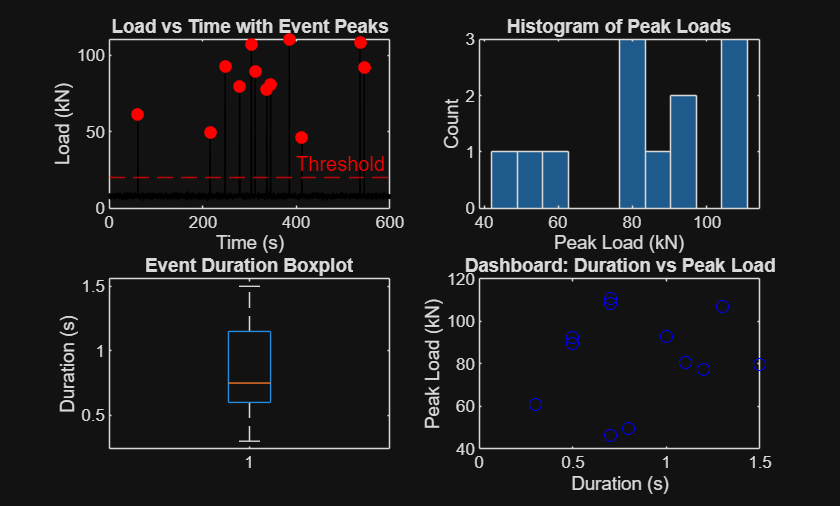

%% Project 15: Bridge Traffic Load Event Detection
clear; clc; close all;

%% -------------------------------------------------------------
% 1. Generate synthetic load vs time data
% -------------------------------------------------------------
fs = 10;                     % sampling rate (Hz)
T  = 600;                    % total duration (s)
t  = (0:1/fs:T)';            % time vector

baseline = 8 + randn(size(t));   % baseline load with noise (kN)

% Create synthetic traffic load events (spikes)
numEvents = 12;                          % number of vehicle events
eventCenters = sort(randi([50, T-50], numEvents, 1));  % random event times
loadData = baseline;                     % initialize load signal

for i = 1:numEvents
    dur = randi([2, 6]);                 % event duration (s)
    width = dur * fs;                    % convert duration to samples
    peak = randi([30, 120]);             % peak load (kN)
    centerIdx = find(t >= eventCenters(i), 1);  % event center index

    % Build Gaussian-like spike around event center
    idx = centerIdx - floor(width/2) : centerIdx + floor(width/2);
    idx = idx(idx > 0 & idx <= length(t));      % ensure valid indices

    spike = peak * exp(-((1:length(idx))' - length(idx)/2).^2 / (0.1*width)^2);
    loadData(idx) = loadData(idx) + spike;      % add spike to signal
end

%% -------------------------------------------------------------
% 2. Event detection using threshold crossing
% -------------------------------------------------------------
threshold = 20;                 % load threshold for event detection (kN)
above = loadData > threshold;   % boolean mask of threshold exceedance

% Detect rising and falling edges of events
d = diff([0; above; 0]);        % prepend/append zeros for edge detection
startIdx = find(d == 1);        % event start indices
endIdx   = find(d == -1) - 1;   % event end indices

numDetected = length(startIdx); % number of detected events

% Preallocate event metrics
eventDur = zeros(numDetected,1);
peakLoad = zeros(numDetected,1);
peakTime = zeros(numDetected,1);

% Compute duration, peak load, and peak time for each event
for i = 1:numDetected
    idx = startIdx(i):endIdx(i);                % event sample range
    eventDur(i) = (endIdx(i) - startIdx(i)) / fs;  % duration (s)

    [peakLoad(i), pIdx] = max(loadData(idx));   % peak load
    peakTime(i) = t(startIdx(i) + pIdx - 1);    % time of peak
end

%% -------------------------------------------------------------
% 3. Visualizations
% -------------------------------------------------------------
figure;

% Time-series with event peaks
subplot(2,2,1)
plot(t, loadData, 'k'); hold on;
yline(threshold, 'r--', 'Threshold');
scatter(peakTime, peakLoad, 40, 'r', 'filled');
title('Load vs Time with Event Peaks');
xlabel('Time (s)'); ylabel('Load (kN)');

% Histogram of peak loads
subplot(2,2,2)
histogram(peakLoad, 10);
title('Histogram of Peak Loads');
xlabel('Peak Load (kN)'); ylabel('Count');

% Boxplot of event durations
subplot(2,2,3)
boxplot(eventDur);
title('Event Duration Boxplot');
ylabel('Duration (s)');

% Dashboard: Duration vs Peak Load
subplot(2,2,4)
plot(eventDur, peakLoad, 'bo');
title('Dashboard: Duration vs Peak Load');
xlabel('Duration (s)'); ylabel('Peak Load (kN)');


%% -------------------------------------------------------------
% 4. Summary table of event statistics
% -------------------------------------------------------------
EventID = (1:numDetected)';     % event numbering
StartTime = t(startIdx);        % event start times
EndTime = t(endIdx);            % event end times
Duration = eventDur;            % event durations

% Build table
EventSummary = table(EventID, StartTime, EndTime, Duration, peakLoad, peakTime);

% Display table in command window
disp(EventSummary);

    EventID    StartTime    EndTime    Duration    peakLoad    peakTime
    _______    _________    _______    ________    ________    ________

       1          61.8        62.1       0.3        60.947       61.9  
       2         215.6       216.4       0.8        49.676      215.9  
       3         247.4       248.4         1        92.577      247.9  
       4         278.2       279.7       1.5         79.62        279  
       5         303.3       304.6       1.3        106.79        304  
       6         311.7       312.2       0.5        89.547        312  
       7         336.4       337.6       1.2        77.498        337  
       8         344.4       345.5       1.1        80.726        345  
       9         384.6       385.3       0.7        110.43      384.9  
   